# 0. 添加路径

currentFolder = pwd;
splitted_str = strsplit(currentFolder,'\');
index = contains(splitted_str,'CableSSB-zh');
if ~any(index)
    error('请进入一个在''CableSSB-zh''内的文件夹')
end
mainpath = '';
for i=1:length(splitted_str)
    if index(i)
        path = join(splitted_str(1:i),'\');
        break
    else
        continue
    end
end
MainPath = genpath(path{1});
addpath(MainPath)

clear all
clc

# 1. 建立桥梁模型

% 协作体系模型
b = CableStayedSuspension_Bridge;
b.build;

Is building a Cable-Stayed Suspension Bridge...


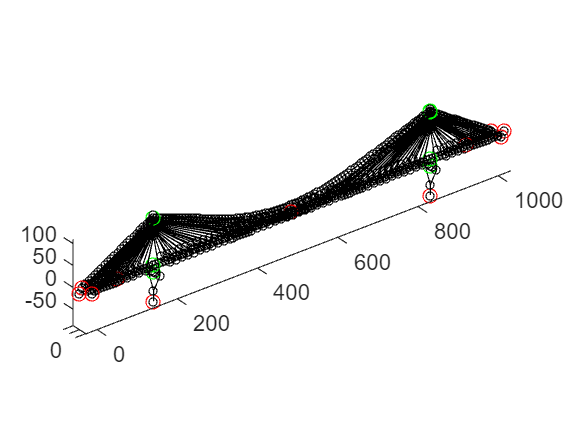

ans =   Figure (1) - 属性:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [440 338 560 420]
       Units: 'pixels'

  显示 所有属性


b.plot

output_method = OutputToAnsys(b,"JobName",'TotalModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\result.out');
b.OutputMethod = output_method;

# 2. 计算无索模型的最小弯曲应变能，获得最优设计竖向力

% 无索模型
bridge_state = NoCable_Bridge(b);
bridge_state.build

Is building a Brigde without Cable System...


output_method = OutputToAnsys(bridge_state,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\result.out');
bridge_state.OutputMethod = output_method;
[FEModel,isEquationCompleted] = bridge_state.getFiniteElementModel;

Is getting Finite Element Model from ANSYS...



% 优化弯曲应变能
bridge_state.optimBendingStrainEnergy('MaxIter',25,'DiffMinChange',1e4);

Is optimizing the Bending Strain Energy...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      79    1.427470e+08    0.000e+00    2.034e+01
    1     158    1.427399e+08    0.000e+00    2.034e+01    8.460e+01
    2     237    1.427041e+08    0.000e+00    2.034e+01    4.230e+02
    3     316    1.425254e+08    0.000e+00    2.033e+01    2.115e+03
    4     395    1.416340e+08    0.000e+00    2.026e+01    1.057e+04
    5     474    1.372382e+08    0.000e+00    1.992e+01    5.265e+04
    6     553    1.167441e+08    0.000e+00    1.823e+01    2.587e+05
    7     632    4.649625e+07    0.000e+00    1.053e+01    1.182e+06
    8     711    1.261748e+07    0.000e+00    2.099e+00    1.571e+06
    9     790    1.261739e+07    0.000e+00    2.099e+00    1.019e+01
   10     869    1.261692e+07    0.000e+00    2.099e+00    4.841e+01
   11     948    1.261461e+07    0.000e+00    2.099e+00    2.420e+02
   1

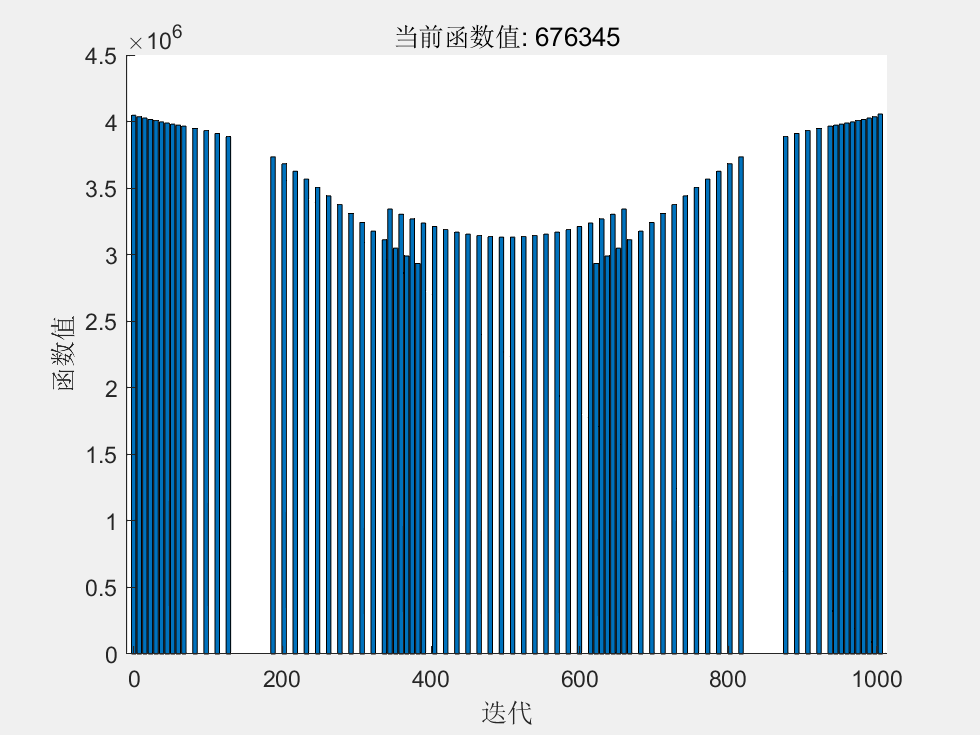


% 结果呈现
Map_Pz = bridge_state.Result_Iteration.Iter_Pz;
max_iter = bridge_state.Iter_Optimization;
Pz_final = Map_Pz(max_iter);
X = bridge_state.OriginalBridge.getSortedGirderPointXCoord([bridge_state.OriginalBridge.findStructureByClass('Hanger'),bridge_state.OriginalBridge.findStructureByClass('StayedCable')]);
bar(X,Pz_final)


% 无索模型的ANSYS结果
output_method = OutputToAnsys(bridge_state,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge\result.out');
bridge_state.OutputMethod = output_method;
bridge_state.output

# 3. 根据最优设计竖向力，将无索模型的设计竖向力恢复到吊索、斜拉索、主缆上

% 根据最优设计竖向力Pz_final, 计算此时的斜拉索力、吊索力、主缆内力

% 计算吊索力和主缆内力
bridge_state.solveCableShape(Pz_final);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      23    1.898264e+05    0.000e+00    8.420e+03
    1      46    1.019482e+03    0.000e+00    7.087e+02    2.888e+01
    2      69    1.512905e+02    0.000e+00    2.698e+02    4.198e+00
    3      92    1.475611e+01    0.000e+00    1.503e+01    3.691e+00
    4     117    9.634511e+00    0.000e+00    1.603e+01    1.546e+00
    5     141    3.050464e+00    0.000e+00    1.565e+01    3.125e+00
    6     164    1.867110e+00    0.000e+00    3.724e+00    1.417e+00
    7     188    8.922504e-01    0.000e+00    7.481e+00    9.193e-01
    8     211    6.458712e-01    0.000e+00    7.574e-01    1.186e+00
    9     234    1.093525e-01    0.000e+00    2.200e+00    7.571e-01
   10     257    7.848034e-02    0.000e+00    3.945e-01    2.689e-01
   11     280    8.074937e-03    0.000e+00    1.526e+00    1.979e-01

fmincon 已停止，因为目标函数值 8.074937e-03 小于
<a href = 

ans = 包含以下字段的 struct :
                   X: [157.2000 164.7000 172.2000 179.7000 187.2000 194.7000 202.2000 209.7000 217.2000 224.7000 232.2000 239.7000 247.2000 254.7000 262.2000 269.7000 277.2000 284.7000 292.2000 299.7000 307.2000 314.7000 322.2000 329.7000 337.2000 … ]
                   Y: [-0.5000 -0.8827 -1.2655 -1.6482 -2.0309 -2.4136 -2.7964 -3.1791 -3.5618 -3.9445 -4.3273 -4.7100 -5.0927 -5.4755 -5.8582 -6.2409 -6.6236 -7.0064 -7.3891 -7.7718 -8.1545 -8.5373 -8.9200 -9.3027 -9.6854 -10.0682 -10.4154 -10.7626 … ]
                   Z: [104.8000 101.7869 98.7789 95.7760 92.7781 89.7854 86.7978 83.8152 80.8378 77.8654 74.8982 71.9360 68.9789 66.0269 63.0800 60.1382 57.2014 54.2697 51.3432 48.4216 45.5052 42.5939 39.6876 36.7864 33.8903 30.9992 28.3777 25.7612 … ]
              Strain: [0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0049 0.0048

resumeSymmetrical called!



% 计算斜拉索索力
X = bridge_state.XCoordOfPz;
for i=1:length(bridge_state.ReplacedStayedCable)
    stayed_cable = bridge_state.ReplacedStayedCable(i);
    Point_Bottom = stayed_cable.findGirderPoint();
    X_Bottom = [Point_Bottom.X];
    P_girder_z = zeros(1,length(X_Bottom));
    for j=1:length(X)
        index = abs(X(j)-X_Bottom) < 1e-5;
        P_girder_z(index) = Pz_final(j);
    end
    stayed_cable.getP(P_girder_z);
end

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


% 导出协作体系桥梁模型到ANSYS
b.output

% 为

# 4. 导出到ANSYS中，查看计算效果

# 如果与实际不相符，则检查模型，特别是其中的实常数

# 5. MATLAB控制ANSYS进行优化，控制初应变，使得达到最优设计竖向力